# Processing Data Samples from MRI

Reference - J. Appl. Phys. 105, 004904  (2009)

## Create Material (Estimate the Response of a Material)

n - Cole Cole Dispersions frequencies (Water has 2)

[http://vosykazoran.weebly.com/uploads/1/2/4/5/12453032/cole_cole_1941.pdf](http://vosykazoran.weebly.com/uploads/1/2/4/5/12453032/cole_cole_1941.pdf)

Time Constant Values 

[http://www.m-hikari.com/astp/astp2008/astp13-16-2008/thakurASTP13-16-2008.pdf](http://www.m-hikari.com/astp/astp2008/astp13-16-2008/thakurASTP13-16-2008.pdf)

Electrical Properties of tissues

[http://andrewamarino.com/PDFs/MB/MB_Ch06.pdf](http://andrewamarino.com/PDFs/MB/MB_Ch06.pdf)

**Cole Cole Dispersions**


$$\varepsilon \left(\omega \right)=\varepsilon_{\infty } +\sum_{m=1}^{n} \frac{\Delta \varepsilon_m }{1+{\left(j\omega \tau_m \right)}^{\left(1-\alpha_m \right)} }+\frac{\sigma_i }{j\omega \varepsilon_0 }$$


clear; clc;

% Physics Values and Name of Material
name = 'Water (Pure)';
p_inf = 4.44;           % Permittivity at infinite frequency (Water)
temp = 25;              % Temperature

% First Debye Relaxation (Water)
p_zero(1) = 80.1        % Permittivity at zero frequency (Water)
t_const(1) = 9.4e-12 % Debye Relaxation Frequency
a(1) = 0.0120           % Dispersion Coefficient
con(1) = 0              % Conductivity

% Second Debye Relaxation (Optional) Use (2) for sescond debye relaxation

freq = logspace(8,11);
e_w = create_material(p_inf, p_zero, t_const, a, con);
save(strcat('materials/', name, '.mat'));

hold on;
semilogx(freq, real(e_w));
semilogx(freq, abs(imag(e_w)));
title('Frequency Response of Dielectric Constant')
xlabel('f/GHz')
ylabel('Permittivity (e)')
legend({'real(e)','imag(e)'})



% Physics values
load('data/materials/MaterialData.mat');

X = 1;
Y = cell2mat(MaterialOrder.LayerThickness).';
[~, h] = size(Y);
Y(2, h) = 0;
Y = fliplr(Y);

% Draw a dielectric layer model from order
figure;
bar(Y,'stacked'); % stacks values in each row together
ax = axis;ax(2) = 1.4; %Change axis limit
axis(ax)
title('Representation of Dielectric Layers');
ylabel('Depth');
legend('show');

## Ultra Wide Band Signal Characteristics

Taken from the Ultra-Wide band signal paper here

[http://digitalcommons.unl.edu/cgi/viewcontent.cgi?article=1058&context=computerelectronicfacpub](http://digitalcommons.unl.edu/cgi/viewcontent.cgi?article=1058&context=computerelectronicfacpub)

[http://www.mathworks.com/matlabcentral/fileexchange/37648-generation-of-uwb-pulse?focused=5238039&tab=function](http://www.mathworks.com/matlabcentral/fileexchange/37648-generation-of-uwb-pulse?focused=5238039&tab=function)

**General zero-mean Gaussian Pulse**


$$p_G \left(t\right)=\mathrm{exp}\left(-2\pi \frac{t^2 }{\tau^2 }\right)$$


**Ricker Pulse (Second Derivative of Gaussian)**


$$\begin{array}{l}
p_G \left(t\right)=\left(2\beta -1\right)\mathrm{exp}\left(-\beta \right)\\
\beta =2\pi \frac{t^2 }{{\tau_0 }^2 }
\end{array}$$


clc; clear;

Fs = 23.328e9; % Samples per second
Bw = 1.5e9;
tao = 1/Bw;
t = -15e-10:1/Fs:15e-10;

% Using The Ricker Pulse (UWB Pulse)
beta = 2*pi*(t/tao).^2

beta =    31.8086   30.0166   28.2764   26.5883   24.9521   23.3678   21.8355   20.3552   18.9268   17.5504   16.2259   14.9534   13.7329   12.5643   11.4476   10.3829    9.3702    8.4094    7.5006    6.6437    5.8388    5.0859    4.3849    3.7359    3.1388    2.5937    2.1005    1.6593    1.2700    0.9327    0.6474    0.4140    0.2326    0.1031    0.0256    0.0000    0.0264    0.1047    0.2351    0.4173    0.6515    0.9377    1.2758    1.6659    2.1080    2.6020    3.1479    3.7458    4.3957    5.0975


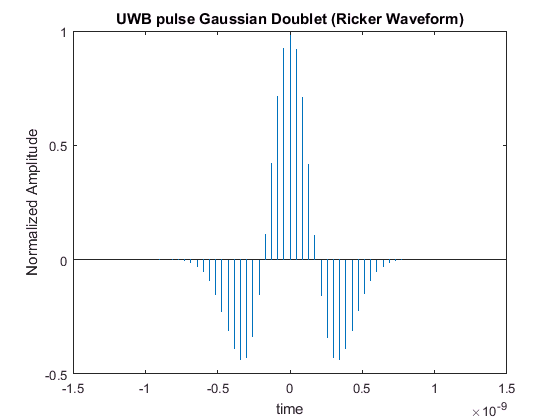

pulse = (1 - 2*beta) .* exp(-beta);

stem(t,pulse, 'Marker', 'None')
xlabel('time');ylabel('Normalized Amplitude');
title('UWB pulse Gaussian Doublet (Ricker Waveform)');

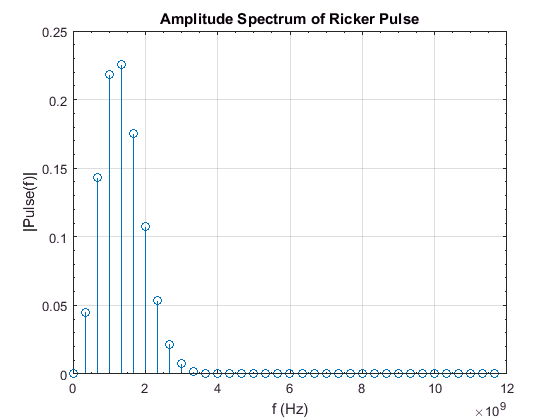


fftPulse = fft(pulse);
L = length(fftPulse);
P2 = abs(fftPulse/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
stem(f,P1) 
title('Amplitude Spectrum of Ricker Pulse')
xlabel('f (Hz)')
ylabel('|Pulse(f)|')
set(gca,'XMinorTick','on','YMinorTick','on');
grid on

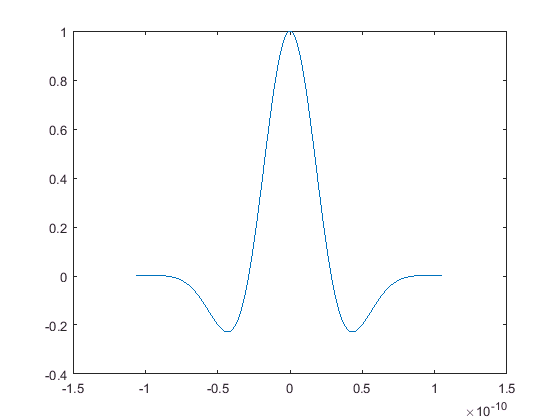


% Using the Xethru Ultra Wideband Pulse
center_freq = 8.748e9;
tc = gauspuls('cutoff',center_freq,2.5,[],-60); 
t = -tc : 1e-12 : tc; 
yi = gauspuls(t,center_freq,1.5); 
plot(t,yi)